# Analiza częstotliwościowa

generowanie probek:

N = 100;
fs1kHz = 1000;
x = 50*sin(2*pi*50*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]) + ...
    100*sin(2*pi*100*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]) + ...
    150*sin(2*pi*150*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]);


% begin exc01
wk = @(k,n) sk(k,N)*cos(pi*(k/N)*(n+0.5));

% generate matrix A
A = zeros(N,N);
for k=0:N-1
    for n=0:N-1
        A(k+1,n+1) = wk(k,n);
    end
end
% end exc01

% begin exc02
S = A.';
% end exc02

prezentacja danych:

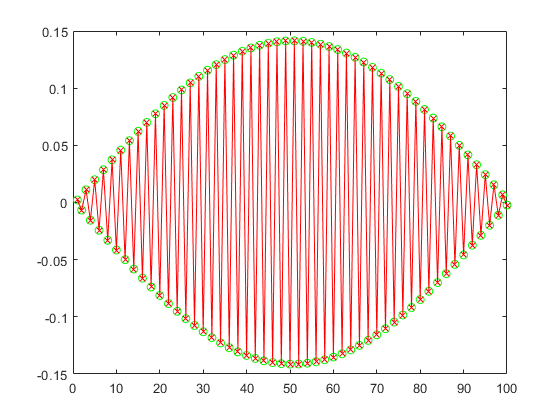

clf
figure
for i=1:N
    clf
    %disp("A: " + A(N,:))
    %disp("S: " + S(:,N)')
    %plot(1:N,A(N,:))
    %plot(1:N,S(:,N)')
    plot(A(i,:),'g-o');
    hold on;
    plot(S(:,i),'r-x');
    pause(0.1)
end

Analiza **y=Ax**

y=A*x';

disp(y');

  Columns 1 through 14

   29.4449   84.3921   42.4794   87.1612   45.3492   93.8864   51.8700  109.1338   69.2267  161.8631  219.0769 -177.8383  -24.5878   38.4575

  Columns 15 through 28

   16.0187   77.2782   35.9183  118.8591   66.7165  236.8054  298.6441 -512.2420  -76.2980  -42.7789  -16.1033   30.5471    9.0362   97.6713

  Columns 29 through 42

   41.8743  281.5883  276.4600 -925.9330 -104.7065 -193.2080  -47.9198 -109.1819  -31.5320  -75.7533  -23.4594  -57.5083  -18.5604  -45.9180

  Columns 43 through 56

  -15.2363  -37.8664  -12.8188  -31.9335  -10.9756  -27.3747   -9.5212  -23.7603   -8.3432  -20.8236   -7.3689  -18.3901   -6.5495  -16.3404

  Columns 57 through 70

   -5.8504  -14.5898   -5.2466  -13.0767   -4.7196  -11.7551   -4.2552  -10.5899   -3.8426   -9.5536   -3.4729   -8.6248   -3.1394   -7.7861

  Columns 71 through 84

   -2.8364   -7.0236   -2.5593   -6.3257   -2.3044   -5.6828   -2.0683   -5.0870   -1.8485   -4.5314   -1.6426   -4.0102   -1.4485   -3.5182



xy=[x;y'];

prezentacja danych

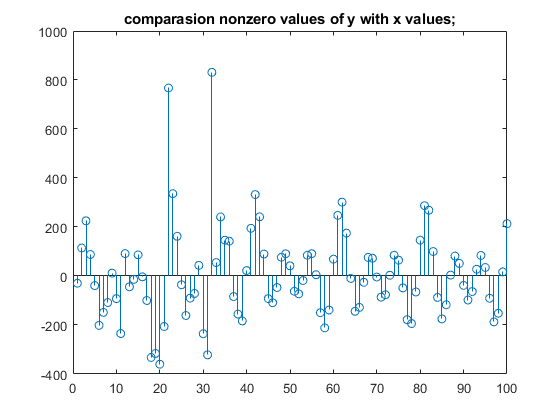

ynotzero = y(round(y,5)~=0);

xynotzero = xy(:, round(xy(2,:),5)~=0 );

% comparasion nonzero values of y with x values;
figure
stem(1:length(xynotzero(1,:)),xynotzero(1,:)-xynotzero(2,:))
%hold on
%stem(1:length(xynotzero(1,:)),xynotzero(2,:))
title("comparasion nonzero values of y with x values;")

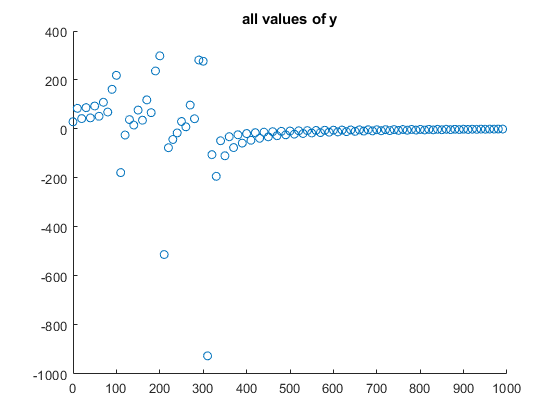


% all values of y
figure
scatter((0:N-1)*fs1kHz/N, y)
title("all values of y")

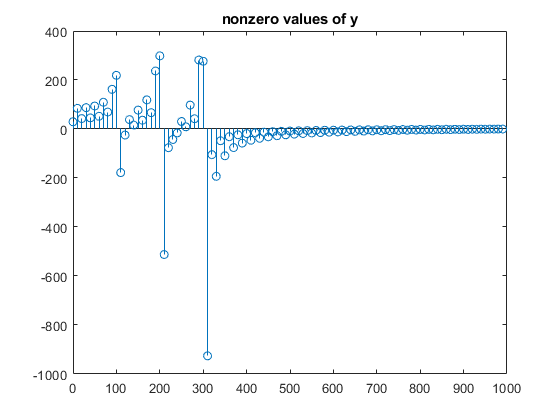


% nonzero values of y
figure
stem((0:length(ynotzero)-1)*fs1kHz/length(ynotzero), ynotzero)
title("nonzero values of y")

Sprawdzanie perfekcyjnej rekonstrukcji:

% TODO

Inna czestotliwosc - z 100hz na 105hz

x = 50*sin(2*pi*50*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]) + ...
    100*sin(2*pi*105*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]) + ...
    150*sin(2*pi*150*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]);

Zwiekszenie wszystkich czestotliwosci o 2.5Hz

x = 50*sin(2*pi*52.5*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]) + ...
    100*sin(2*pi*102.5*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]) + ...
    150*sin(2*pi*152.5*[0:1/fs1kHz:N*1/fs1kHz-1/fs1kHz]);

function s = sk(k,N)
    if k==0
        s = sqrt(1/N);
        return
    end
    s = sqrt(2/N);
end